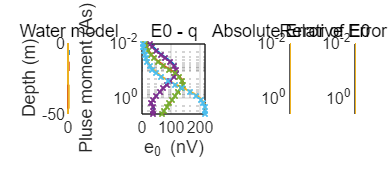

clear;clc;
%close all;
folderPath = fullfile(pwd);

MData_bloch0 = load(fullfile(folderPath, ...
    '2504-fig6-e05/100-600-300-bloch-250428-1-0.5.mat'));
MData_bloch1 = load(fullfile(folderPath, ...
    '2504-fig6-e05/100-600-300-bloch-250428-2-0.5.mat'));
MData_bloch2 = load(fullfile(folderPath, ...
    '2504-fig6-e05/100-600-300-bloch-250428-3-0.5.mat'));
% MData_bloch3 = load(fullfile(folderPath, ...
%     '2504-fig6-e0/a/100-600-300-bloch-250426-1-0.2.mat'));
% MData_bloch4 = load(fullfile(folderPath, ...
%     '2504-fig6-e0/a/100-600-300-bloch-250426-2-0.2.mat'));
% MData_bloch5 = load(fullfile(folderPath, ...
%     '2504-fig6-e0/a/100-600-300-bloch-250426-3-0.2.mat'));
MData_RK40 = load(fullfile(folderPath, ...
    '2504-fig6-e05/100-600-300-RK4-250428-1-0.5.mat'));
MData_RK41 = load(fullfile(folderPath, ...
    '2504-fig6-e05/100-600-300-RK4-250428-2-0.5.mat'));
MData_RK42 = load(fullfile(folderPath, ...
    '2504-fig6-e05/100-600-300-RK4-250428-3-0.5.mat'));
% MData_RK43 = load(fullfile(folderPath, ...
%     '2504-fig6-e0/a/100-600-300-RK4-250426-1-0.2.mat'));
% MData_RK44 = load(fullfile(folderPath, ...
%     '2504-fig6-e0/a/100-600-300-RK4-250426-2-0.2.mat'));
% MData_RK45 = load(fullfile(folderPath, ...
%     '2504-fig6-e0/a/100-600-300-RK4-250426-3-0.2.mat'));

M_bloch0 = MData_bloch0.jlmrsData;
M_bloch1 = MData_bloch1.jlmrsData;
M_bloch2 = MData_bloch2.jlmrsData;
% M_bloch3 = MData_bloch3.jlmrsData;
% M_bloch4 = MData_bloch4.jlmrsData;
% M_bloch5 = MData_bloch5.jlmrsData;
M_RK40 = MData_RK40.jlmrsData;
M_RK41 = MData_RK41.jlmrsData;
M_RK42 = MData_RK42.jlmrsData;
% M_RK43 = MData_RK43.jlmrsData;
% M_RK44 = MData_RK44.jlmrsData;
% M_RK45 = MData_RK45.jlmrsData;

water0 = M_bloch0.model.water;
water1 = M_bloch1.model.water;
water2 = M_bloch2.model.water;
% water3 = M_bloch3.model.water;
% water4 = M_bloch4.model.water;
% water5 = M_bloch5.model.water;
z_vec = M_bloch0.model.z_vec;

e0_bloch0 = abs(M_bloch0.model.e0)*1e9;
e0_bloch1 = abs(M_bloch1.model.e0)*1e9;
e0_bloch2 = abs(M_bloch2.model.e0)*1e9;
% e0_bloch3 = abs(M_bloch3.model.e0)*1e9;
% e0_bloch4 = abs(M_bloch4.model.e0)*1e9;
% e0_bloch5 = abs(M_bloch5.model.e0)*1e9;
e0_RK40 = abs(M_RK40.model.e0)*1e9;
e0_RK41 = abs(M_RK41.model.e0)*1e9;
e0_RK42 = abs(M_RK42.model.e0)*1e9;
% e0_RK43 = abs(M_RK43.model.e0)*1e9;
% e0_RK44 = abs(M_RK44.model.e0)*1e9;
% e0_RK45 = abs(M_RK45.model.e0)*1e9;
e0_Loss0 = abs(e0_bloch0-e0_RK40);
e0_Loss1 = abs(e0_bloch1-e0_RK41);
e0_Loss2 = abs(e0_bloch2-e0_RK42);
% e0_Loss3 = abs(e0_bloch3-e0_RK43);
% e0_Loss4 = abs(e0_bloch4-e0_RK44);
% e0_Loss5 = abs(e0_bloch5-e0_RK45);
e0_RLoss0 = e0_Loss0./e0_RK40;
e0_RLoss1 = e0_Loss1./e0_RK41;
e0_RLoss2 = e0_Loss2./e0_RK42;
% e0_RLoss3 = e0_Loss3./e0_RK43;
% e0_RLoss4 = e0_Loss4./e0_RK44;
% e0_RLoss5 = e0_Loss5./e0_RK45;
z_pluse = M_bloch0.measure.qobs;

figure;
tiledlayout(1,5)
set(gcf, 'Units', 'centimeters', 'Position', [0 0 16.8 8]);
nexttile(1)
hold on
hs0 = stairs([water0(1);water0]*100,z_vec);
hs1 = stairs([water1(1);water1]*100,z_vec);
hs2 = stairs([water2(1);water2]*100,z_vec);
% hs3 = stairs([water3(1);water3]*100,z_vec);
% hs4 = stairs([water4(1);water4]*100,z_vec);
% hs5 = stairs([water5(1);water5]*100,z_vec);
ylabel('Depth (m)')
xlabel('Water content (%)')
set([hs0, hs1, hs2], 'LineStyle', '-', 'LineWidth', 1)
% set([hs3, hs4, hs5], 'LineStyle', '-.', 'LineWidth', 1)
axis([0, max(water1*100)*1.2, min(z_vec), max(z_vec)])
title('Water model')
grid on
box on

nexttile([1 2])
hold on
hs0 = plot(e0_bloch0,z_pluse,'-');
hs2 = plot(e0_bloch1,z_pluse,'-');
hs4 = plot(e0_bloch2,z_pluse,'-');
% hs6 = plot(e0_bloch3,z_pluse,'-.');
% hs8 = plot(e0_bloch4,z_pluse,'-.');
% hs10 = plot(e0_bloch5,z_pluse,'-.');
hs1 = plot(e0_RK40,z_pluse,'x');
hs3 = plot(e0_RK41,z_pluse,'x');
hs5 = plot(e0_RK42,z_pluse,'x');
% hs7 = plot(e0_RK43,z_pluse,'x');
% hs9 = plot(e0_RK44,z_pluse,'x');
% hs11 = plot(e0_RK45,z_pluse,'x');
ylabel('Pluse moment (As)')
xlabel('e_0 (nV)')
set([hs0, hs2, hs4], 'LineWidth', 1)
set([hs1, hs3, hs5], 'LineWidth', 1, 'MarkerSize', 3.8)
set(gca, 'YDir', 'reverse')
set(gca, 'YScale', 'log')
% set(gca, 'YLim', [0.04, 4])
set(gca, 'YLim', [0.01, 4])
title('E0 - q')
grid on
box on

nexttile(4)
hold on
hs0 = plot(e0_Loss0,z_pluse,'-');
hs1 = plot(e0_Loss1,z_pluse,'-');
hs2 = plot(e0_Loss2,z_pluse,'-');
% hs3 = plot(e0_Loss3,z_pluse,'-.');
% hs4 = plot(e0_Loss4,z_pluse,'-.');
% hs5 = plot(e0_Loss5,z_pluse,'-.');
% ylabel('Pluse moment (As)')
xlabel('e_0 (nV)')
set([hs0, hs1, hs2], 'LineWidth', 1)
set(gca, 'YDir', 'reverse')
set(gca, 'YScale', 'log')
% set(gca, 'YLim', [0.04, 4])
set(gca, 'YLim', [0.01, 4])
title('Absolute Error of E0')
grid on
box on

nexttile(5)
hold on
hs0 = plot(e0_RLoss0*100,z_pluse,'-');
hs1 = plot(e0_RLoss1*100,z_pluse,'-');
hs2 = plot(e0_RLoss2*100,z_pluse,'-');
% hs3 = plot(e0_RLoss3*100,z_pluse,'-.');
% hs4 = plot(e0_RLoss4*100,z_pluse,'-.');
% hs5 = plot(e0_RLoss5*100,z_pluse,'-.');
% ylabel('Pluse moment (As)')
xlabel('Percent (%)')
set([hs0, hs1, hs2], 'LineWidth', 1)
set(gca, 'YDir', 'reverse')
set(gca, 'YScale', 'log')
% set(gca, 'YLim', [0.04, 4])
set(gca, 'YLim', [0.01, 4])
title('Relative Error of E0')
grid on
box on

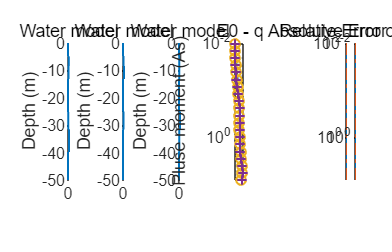

% b
clear;clc;
%close all;
folderPath = fullfile(pwd);
Model = load(fullfile(folderPath, '2504-Fig6-e06/model.mat'));
MData_bloch0 = load(fullfile(folderPath, '2504-Fig6-e06/100-1-bloch.mat'));
MData_bloch1 = load(fullfile(folderPath, '2504-Fig6-e06/100-2-bloch.mat'));
MData_bloch2 = load(fullfile(folderPath, '2504-Fig6-e06/100-3-bloch.mat'));
MData_bloch3 = load(fullfile(folderPath, '2504-Fig6-e06/100-4-bloch.mat'));
MData_bloch4 = load(fullfile(folderPath, '2504-Fig6-e06/200-1-bloch.mat'));
MData_bloch5 = load(fullfile(folderPath, '2504-Fig6-e06/200-2-bloch.mat'));
MData_bloch6 = load(fullfile(folderPath, '2504-Fig6-e06/200-3-bloch.mat'));
MData_bloch7 = load(fullfile(folderPath, '2504-Fig6-e06/200-4-bloch.mat'));
MData_RK40 = load(fullfile(folderPath, '2504-Fig6-e06/100-1-RK4.mat'));
MData_RK41 = load(fullfile(folderPath, '2504-Fig6-e06/100-2-RK4.mat'));
MData_RK42 = load(fullfile(folderPath, '2504-Fig6-e06/100-3-RK4.mat'));
MData_RK43 = load(fullfile(folderPath, '2504-Fig6-e06/100-4-RK4.mat'));
MData_RK44 = load(fullfile(folderPath, '2504-Fig6-e06/200-1-RK4.mat'));
MData_RK45 = load(fullfile(folderPath, '2504-Fig6-e06/200-2-RK4.mat'));
MData_RK46 = load(fullfile(folderPath, '2504-Fig6-e06/200-3-RK4.mat'));
MData_RK47 = load(fullfile(folderPath, '2504-Fig6-e06/200-4-RK4.mat'));

M_bloch0 = MData_bloch0.jlmrsData.model.e0*1e9;
M_bloch1 = MData_bloch1.jlmrsData.model.e0*1e9;
M_bloch2 = MData_bloch2.jlmrsData.model.e0*1e9;
M_bloch3 = MData_bloch3.jlmrsData.model.e0*1e9;
M_bloch4 = MData_bloch4.jlmrsData.model.e0*1e9;
M_bloch5 = MData_bloch5.jlmrsData.model.e0*1e9;
M_bloch6 = MData_bloch6.jlmrsData.model.e0*1e9;
M_bloch7 = MData_bloch7.jlmrsData.model.e0*1e9;
M_RK40 = MData_RK40.jlmrsData.model.e0*1e9;
M_RK41 = MData_RK41.jlmrsData.model.e0*1e9;
M_RK42 = MData_RK42.jlmrsData.model.e0*1e9;
M_RK43 = MData_RK43.jlmrsData.model.e0*1e9;
M_RK44 = MData_RK44.jlmrsData.model.e0*1e9;
M_RK45 = MData_RK45.jlmrsData.model.e0*1e9;
M_RK46 = MData_RK46.jlmrsData.model.e0*1e9;
M_RK47 = MData_RK47.jlmrsData.model.e0*1e9;

water0 = Model.jlmrsData.model.water;
t1s = Model.jlmrsData.model.t1s;
t2s = Model.jlmrsData.model.t2s;
z_vec = MData_bloch0.jlmrsData.model.z_vec;

e0_bloch100 = abs(M_bloch0+M_bloch1+M_bloch2+M_bloch3);
e0_bloch200 = abs(M_bloch4+M_bloch5+M_bloch6+M_bloch7);
e0_RK4100 = abs(M_RK40+M_RK41+M_RK42+M_RK43);
e0_RK4200 = abs(M_RK44+M_RK45+M_RK46+M_RK47);

e0_Loss0 = abs(e0_bloch100-e0_RK4100);
e0_Loss1 = abs(e0_bloch200-e0_RK4200);

e0_RLoss0 = e0_Loss0./e0_RK4100;
e0_RLoss1 = e0_Loss1./e0_RK4200;

z_pluse =MData_bloch0.jlmrsData.measure.qobs;

figure;
tiledlayout(1,7)
set(gcf, 'Units', 'centimeters', 'Position', [0 0 28 18]);
nexttile(1)
hold on
hs0 = stairs([water0(1);water0]*100,z_vec);
ylabel('Depth (m)')
xlabel('Water content (%)')
set([hs0], 'LineStyle', '-', 'LineWidth', 1)
axis([0, 40, min(z_vec), max(z_vec)])
title('Water model')
grid on
box on

nexttile(2)
hold on
hs1 = stairs([t1s(1);t1s]*1000,z_vec);
ylabel('Depth (m)')
xlabel('Water content (%)')
set([hs1], 'LineStyle', '-', 'LineWidth', 1)
axis([0, 1000, min(z_vec), max(z_vec)])
title('Water model')
grid on
box on

nexttile(3)
hold on
hs2 = stairs([t2s(1);t2s]*1000,z_vec);
ylabel('Depth (m)')
xlabel('Water content (%)')
set([hs2], 'LineStyle', '-', 'LineWidth', 1)
axis([0, 300, min(z_vec), max(z_vec)])
title('Water model')
grid on
box on

nexttile([1 2])
hold on
hs0 = plot(e0_bloch100,z_pluse,'-');
hs2 = plot(e0_bloch200,z_pluse,'-.');
hs1 = plot(e0_RK4100,z_pluse,'o');
hs3 = plot(e0_RK4200,z_pluse,'+');
ylabel('Pluse moment (As)')
xlabel('e_0 (nV)')
set([hs0, hs2], 'LineWidth', 1)
set([hs1, hs3], 'LineWidth', 1, 'MarkerSize', 4.8)
set(gca, 'YDir', 'reverse')
set(gca, 'YScale', 'log')
set(gca, 'YLim', [0.01, 8])
title('E0 - q')
grid on
box on

nexttile(6)
hold on
hs0 = plot(e0_Loss0,z_pluse,'-');
hs1 = plot(e0_Loss1,z_pluse,'-.');
% ylabel('Pluse moment (As)')
xlabel('e_0 (nV)')
set([hs0, hs1], 'LineWidth', 1)
set(gca, 'YDir', 'reverse')
set(gca, 'YScale', 'log')
set(gca, 'YLim', [0.01, 8])
title('Absolute Error of E0')
grid on
box on

nexttile(7)
hold on
hs0 = plot(e0_RLoss0*100,z_pluse,'-');
hs1 = plot(e0_RLoss1*100,z_pluse,'-.');
% ylabel('Pluse moment (As)')
xlabel('Percent (%)')
set([hs0, hs1, hs2], 'LineWidth', 1)
set(gca, 'YDir', 'reverse')
set(gca, 'YScale', 'log')
set(gca, 'YLim', [0.01, 8])
title('Relative Error of E0')
grid on
box on

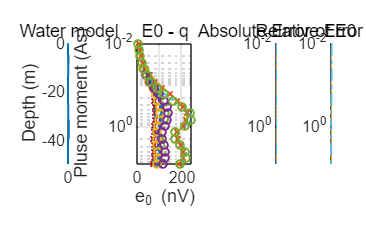

clear;clc;
%close all;
folderPath = fullfile(pwd);

MData_bloch0 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/100-1000-100-bloch-250428.mat'));
MData_bloch1 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/100-500-100-bloch-250428.mat'));
MData_bloch2 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/100-100-100-bloch-250428.mat'));
MData_bloch3 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/200-1000-100-bloch-250428.mat'));
MData_bloch4 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/200-500-100-bloch-250428.mat'));
MData_bloch5 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/200-100-100-bloch-250428.mat'));
MData_RK40 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/100-1000-100-RK4-250428.mat'));
MData_RK41 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/100-500-100-RK4-250428.mat'));
MData_RK42 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/100-100-100-RK4-250428.mat'));
MData_RK43 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/200-1000-100-RK4-250428.mat'));
MData_RK44 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/200-500-100-RK4-250428.mat'));
MData_RK45 = load(fullfile(folderPath, ...
    '2504-Fig6-e05/200-100-100-RK4-250428.mat'));

M_bloch0 = MData_bloch0.jlmrsData;
M_bloch1 = MData_bloch1.jlmrsData;
M_bloch2 = MData_bloch2.jlmrsData;
M_bloch3 = MData_bloch3.jlmrsData;
M_bloch4 = MData_bloch4.jlmrsData;
M_bloch5 = MData_bloch5.jlmrsData;
M_RK40 = MData_RK40.jlmrsData;
M_RK41 = MData_RK41.jlmrsData;
M_RK42 = MData_RK42.jlmrsData;
M_RK43 = MData_RK43.jlmrsData;
M_RK44 = MData_RK44.jlmrsData;
M_RK45 = MData_RK45.jlmrsData;

water0 = M_bloch0.model.water;
water1 = M_bloch1.model.water;
water2 = M_bloch2.model.water;
water3 = M_bloch3.model.water;
water4 = M_bloch4.model.water;
water5 = M_bloch5.model.water;
z_vec = M_bloch0.model.z_vec;

e0_bloch0 = abs(M_bloch0.model.e0)*1e9;
e0_bloch1 = abs(M_bloch1.model.e0)*1e9;
e0_bloch2 = abs(M_bloch2.model.e0)*1e9;
e0_bloch3 = abs(M_bloch3.model.e0)*1e9;
e0_bloch4 = abs(M_bloch4.model.e0)*1e9;
e0_bloch5 = abs(M_bloch5.model.e0)*1e9;
e0_RK40 = abs(M_RK40.model.e0)*1e9;
e0_RK41 = abs(M_RK41.model.e0)*1e9;
e0_RK42 = abs(M_RK42.model.e0)*1e9;
e0_RK43 = abs(M_RK43.model.e0)*1e9;
e0_RK44 = abs(M_RK44.model.e0)*1e9;
e0_RK45 = abs(M_RK45.model.e0)*1e9;
e0_Loss0 = abs(e0_bloch0-e0_RK40);
e0_Loss1 = abs(e0_bloch1-e0_RK41);
e0_Loss2 = abs(e0_bloch2-e0_RK42);
e0_Loss3 = abs(e0_bloch3-e0_RK43);
e0_Loss4 = abs(e0_bloch4-e0_RK44);
e0_Loss5 = abs(e0_bloch5-e0_RK45);
e0_RLoss0 = e0_Loss0./e0_RK40;
e0_RLoss1 = e0_Loss1./e0_RK41;
e0_RLoss2 = e0_Loss2./e0_RK42;
e0_RLoss3 = e0_Loss3./e0_RK43;
e0_RLoss4 = e0_Loss4./e0_RK44;
e0_RLoss5 = e0_Loss5./e0_RK45;
z_pluse = M_bloch0.measure.qobs;

figure;
tiledlayout(1,5)
set(gcf, 'Units', 'centimeters', 'Position', [0 0 28 18]);
nexttile(1)
hold on
hs0 = stairs([water0(1);water0]*100,z_vec);
ylabel('Depth (m)')
xlabel('Water content (%)')
set(hs0, 'LineStyle', '-', 'LineWidth', 1)
axis([0, max(water1*100)*1.2, min(z_vec), max(z_vec)])
title('Water model')
grid on
box on

nexttile([1 2])
hold on
hs0 = plot(e0_bloch0,z_pluse,'-');
hs2 = plot(e0_bloch1,z_pluse,'-');
hs4 = plot(e0_bloch2,z_pluse,'-');
hs6 = plot(e0_bloch3,z_pluse,'-.');
hs8 = plot(e0_bloch4,z_pluse,'-.');
hs10 = plot(e0_bloch5,z_pluse,'-.');
hs1 = plot(e0_RK40,z_pluse,'x');
hs3 = plot(e0_RK41,z_pluse,'x');
hs5 = plot(e0_RK42,z_pluse,'x');
hs7 = plot(e0_RK43,z_pluse,'o');
hs9 = plot(e0_RK44,z_pluse,'o');
hs11 = plot(e0_RK45,z_pluse,'o');
ylabel('Pluse moment (As)')
xlabel('e_0 (nV)')
set([hs0, hs2, hs4, hs6, hs8, hs10,], 'LineWidth', 1)
set([hs1, hs3, hs5, hs7, hs9, hs11], 'LineWidth', 1, 'MarkerSize', 3.8)
set(gca, 'YDir', 'reverse')
set(gca, 'YScale', 'log')
set(gca, 'YLim', [0.01, 8])
title('E0 - q')
grid on
box on

nexttile(4)
hold on
hs0 = plot(e0_Loss0,z_pluse,'-');
hs1 = plot(e0_Loss1,z_pluse,'-');
hs2 = plot(e0_Loss2,z_pluse,'-');
hs3 = plot(e0_Loss3,z_pluse,'-.');
hs4 = plot(e0_Loss4,z_pluse,'-.');
hs5 = plot(e0_Loss5,z_pluse,'-.');
% ylabel('Pluse moment (As)')
xlabel('e_0 (nV)')
set([hs0, hs1, hs2, hs3, hs4, hs5], 'LineWidth', 1)
set(gca, 'YDir', 'reverse')
set(gca, 'YScale', 'log')
set(gca, 'YLim', [0.01, 8])
title('Absolute Error of E0')
grid on
box on

nexttile(5)
hold on
hs0 = plot(e0_RLoss0*100,z_pluse,'-');
hs1 = plot(e0_RLoss1*100,z_pluse,'-');
hs2 = plot(e0_RLoss2*100,z_pluse,'-');
hs3 = plot(e0_RLoss3*100,z_pluse,'-.');
hs4 = plot(e0_RLoss4*100,z_pluse,'-.');
hs5 = plot(e0_RLoss5*100,z_pluse,'-.');
% ylabel('Pluse moment (As)')
xlabel('Percent (%)')
set([hs0, hs1, hs2], 'LineWidth', 1)
set(gca, 'YDir', 'reverse')
set(gca, 'YScale', 'log')
set(gca, 'YLim', [0.01, 8])
title('Relative Error of E0')
grid on
box on